# Social Networks Analysis Assignment

fileID = fopen('sx-stackoverflow.txt','r');
formatSpec = '%d %d %d';
sizeA = [3 3000];
Data = fscanf(fileID,formatSpec,sizeA);
Data = Data';

Enter the number of distinct time frames

N = 4

N = 4

Pgd = 5

Pgd = 5

Pcn = 5

Pcn = 5

Pjc = 5

Pjc = 5


Pa = 5

Pa = 5


Ppa = 5

Ppa = 5

**1ο ερώτημα**

startTime = min(Data(:,3))

startTime = 1.2176e+09

endTime = max(Data(:,3))

endTime = 1.2197e+09

**2ο ερώτημα**

Timestamps = zeros(1,N+1);
for i = 1:1:N+1
    Timestamps(i) = startTime + i*((endTime-startTime)/(N+1));
end

Timestamps

Timestamps = 	1.0e+09 *

    1.2180    1.2184    1.2188    1.2192    1.2197


**3ο ερώτημα**

Graphs = {digraph};

for i = 2:1:N
    Graphs{end+1} = digraph;
end

len = size(Data,1);

for i = 1:1:len
    k=1;
    for j = Timestamps(2:end)
    
        if Data(i,3) < j
            
            Graphs{k} = addedge(Graphs{k},int2str(Data(i,1)),int2str(Data(i,2)));
            break
        end
        k = k+1;
    end
    
end

numnodes(Graphs{1})

ans = 491

numnodes(Graphs{2})

ans = 593

numnodes(Graphs{3})

ans = 780

numnodes(Graphs{4})

ans = 1056

**4ο ερώτημα**

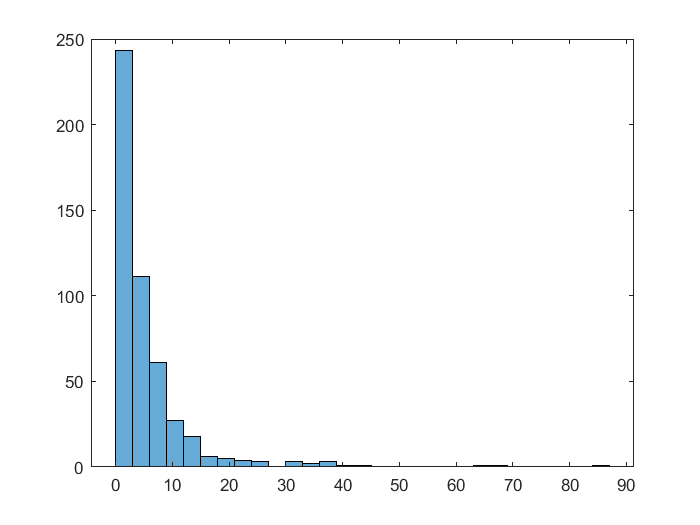

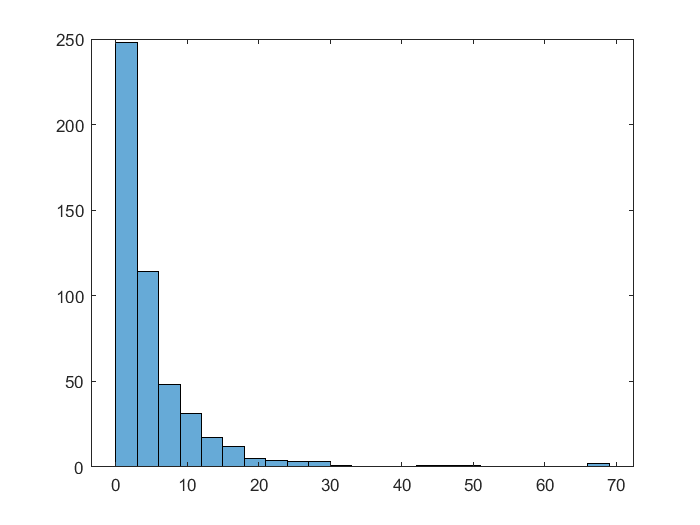

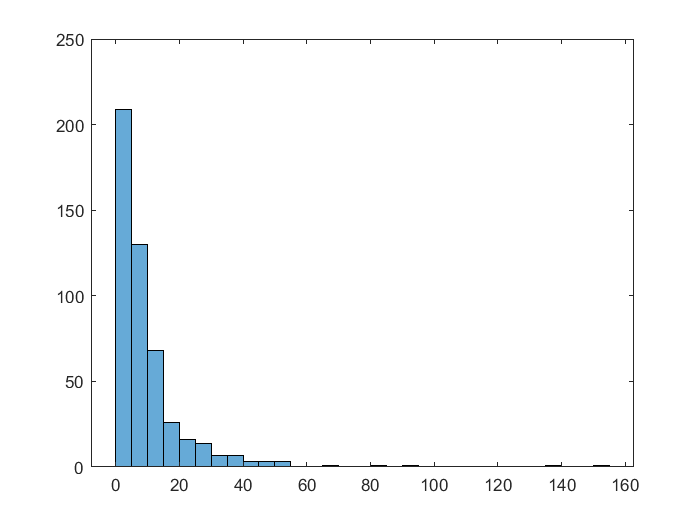

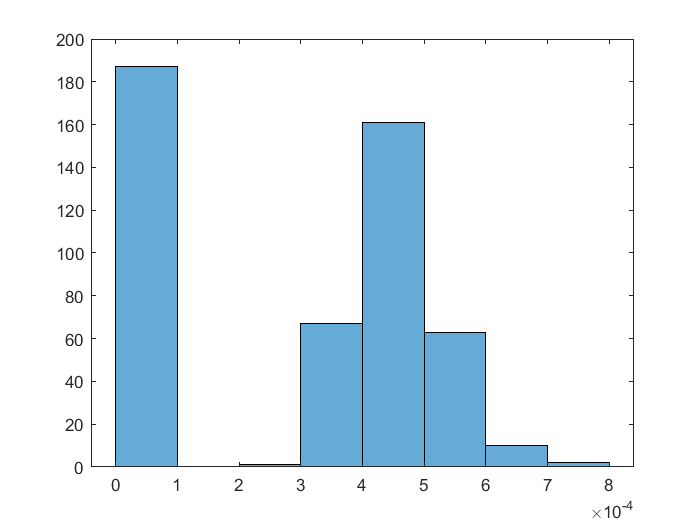

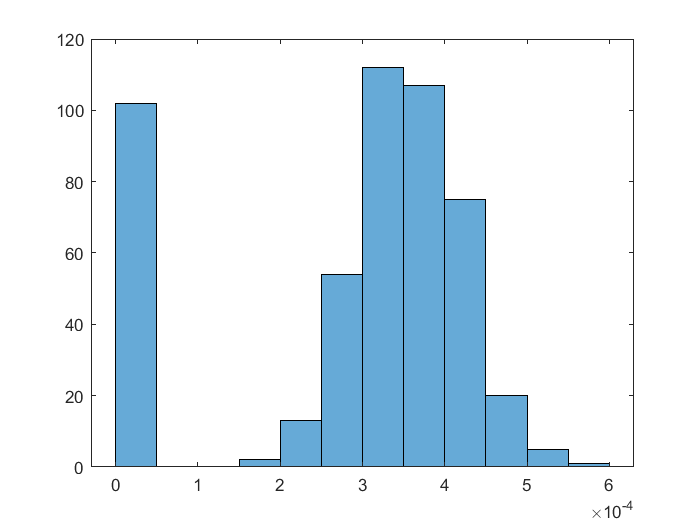

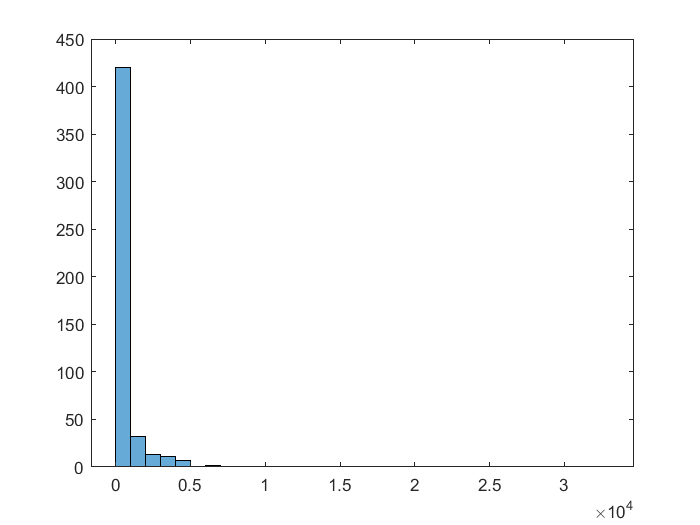

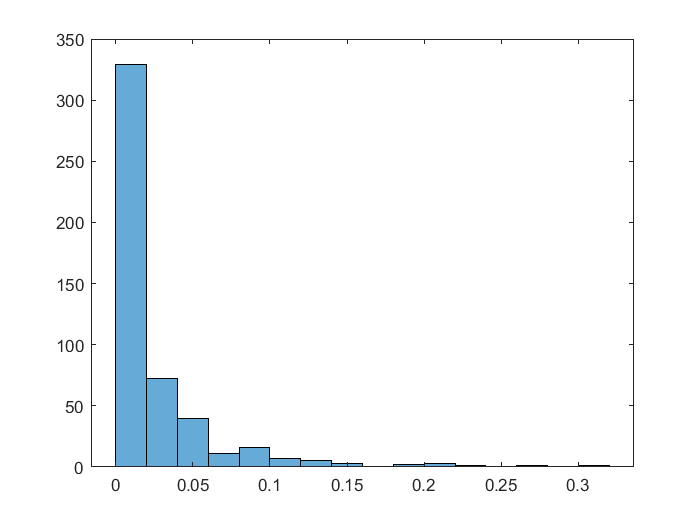

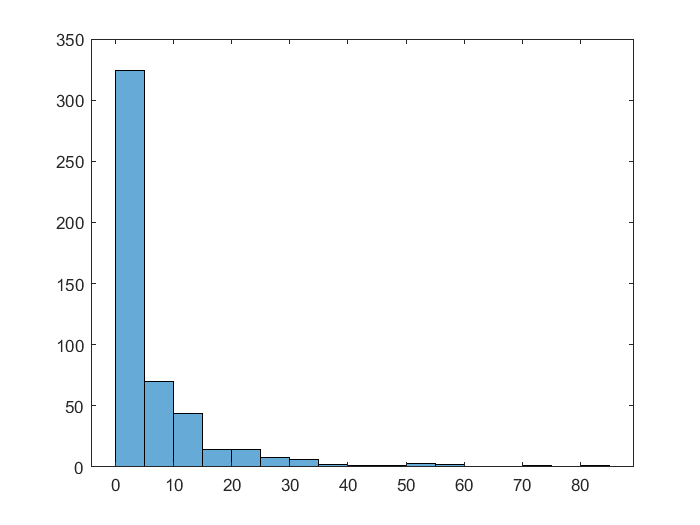

graph


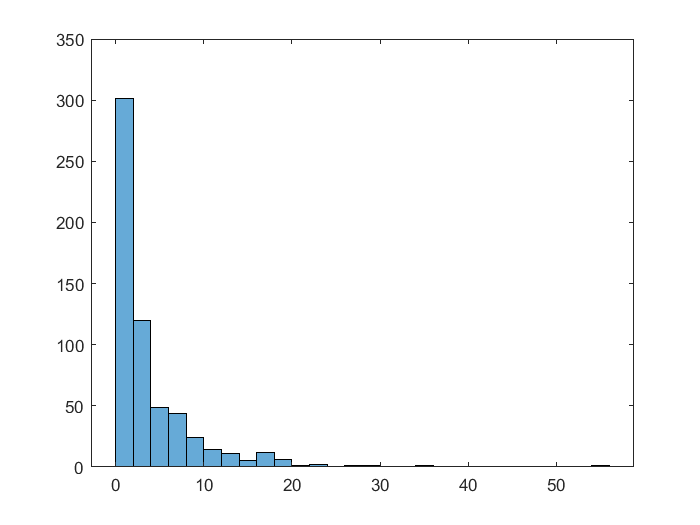

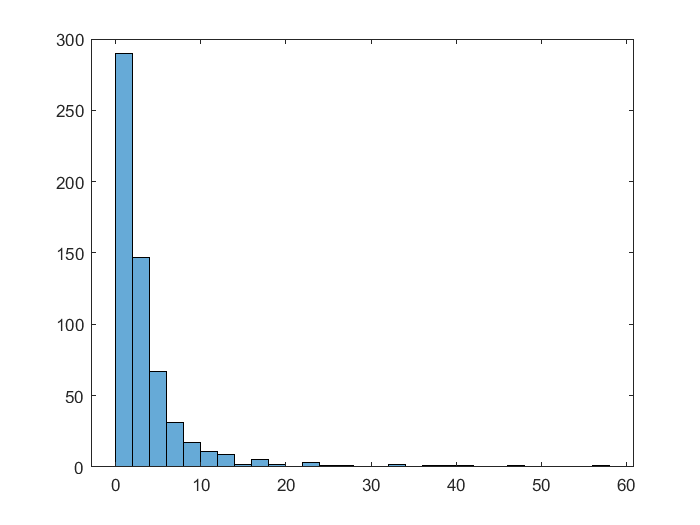

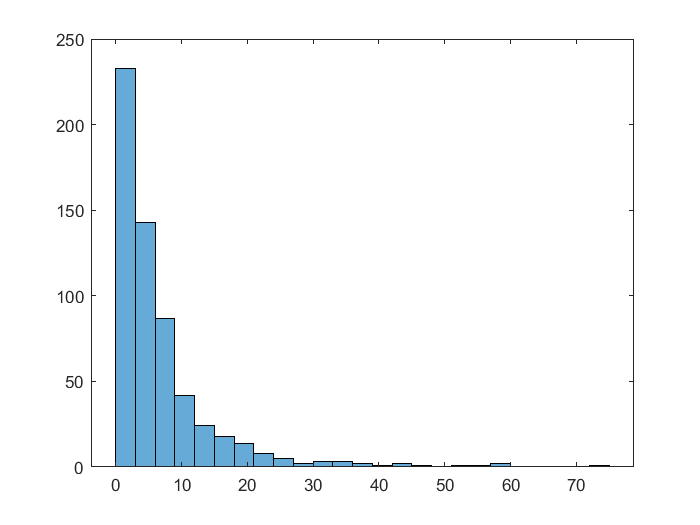

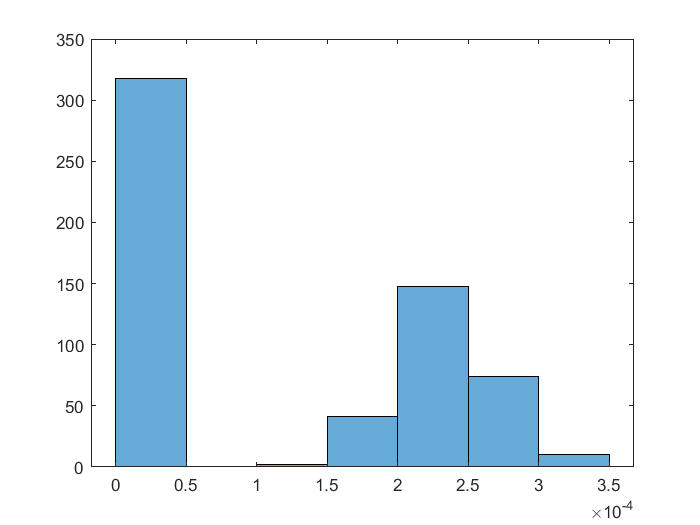

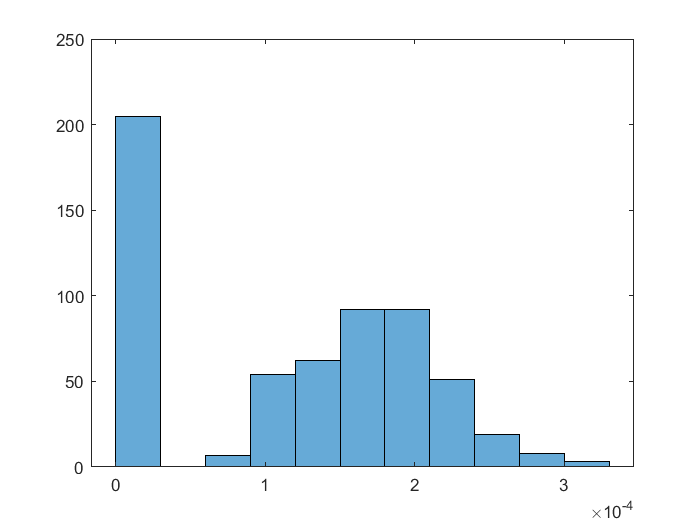

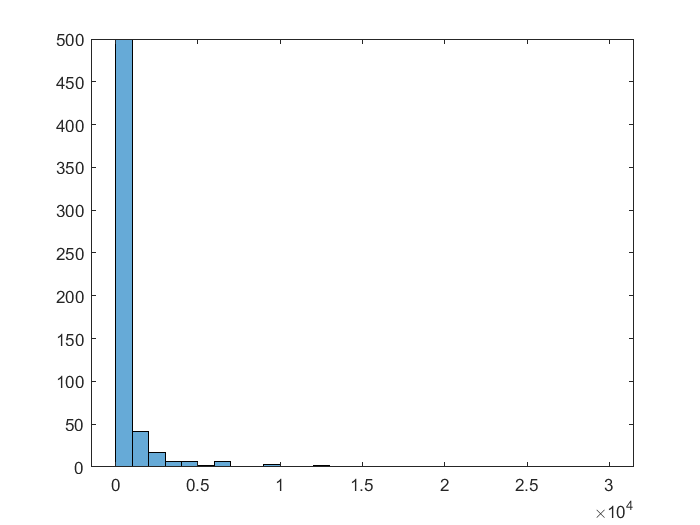

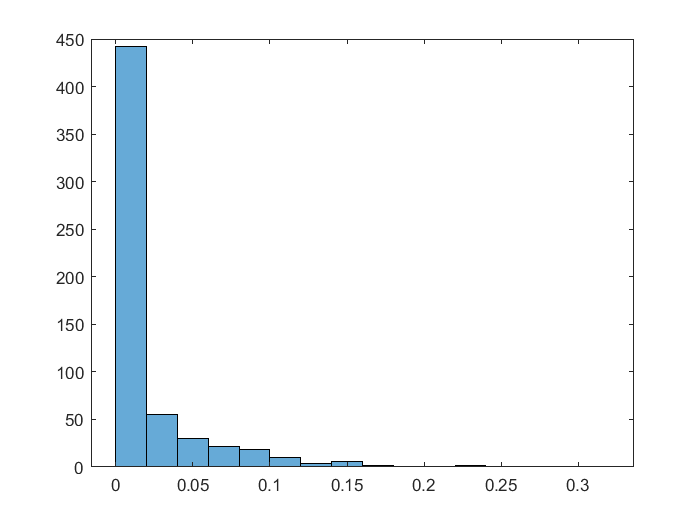

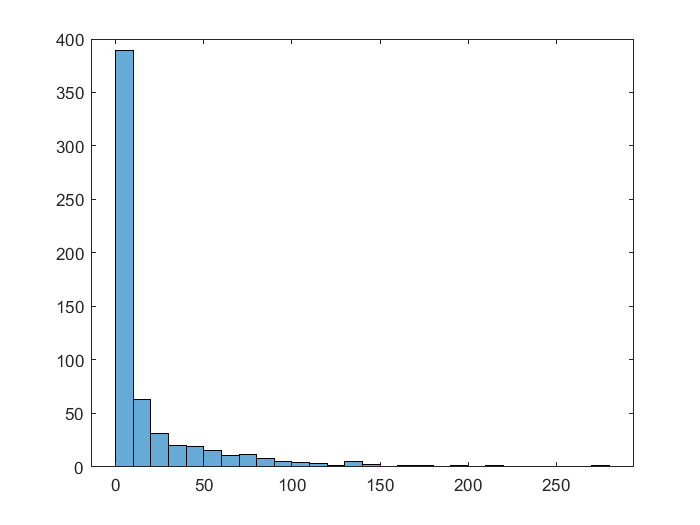

graph


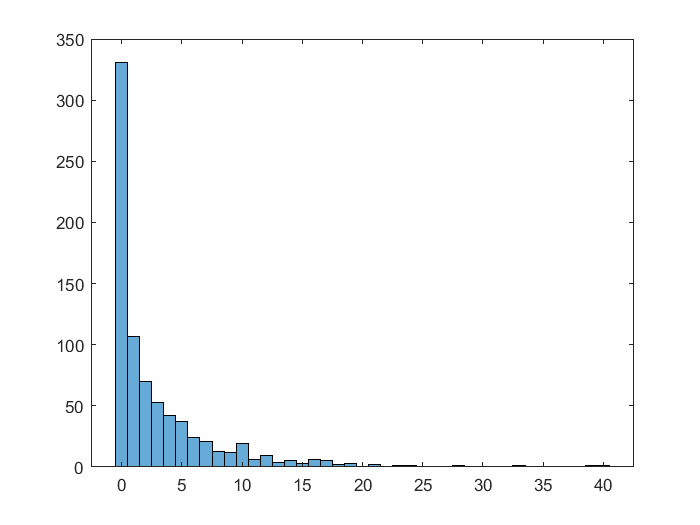

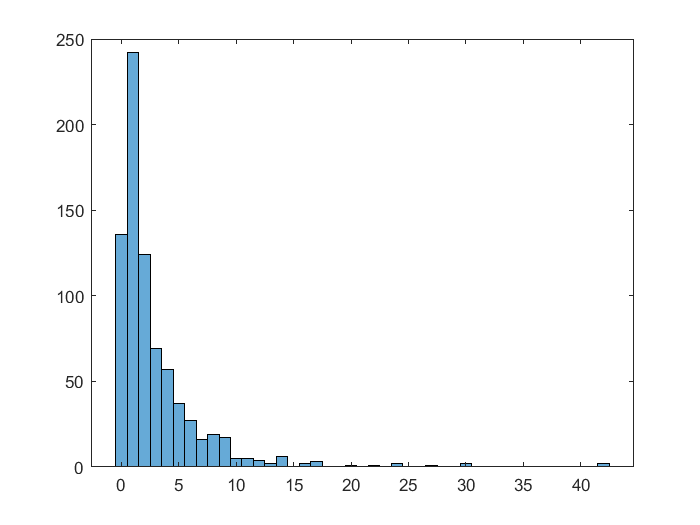

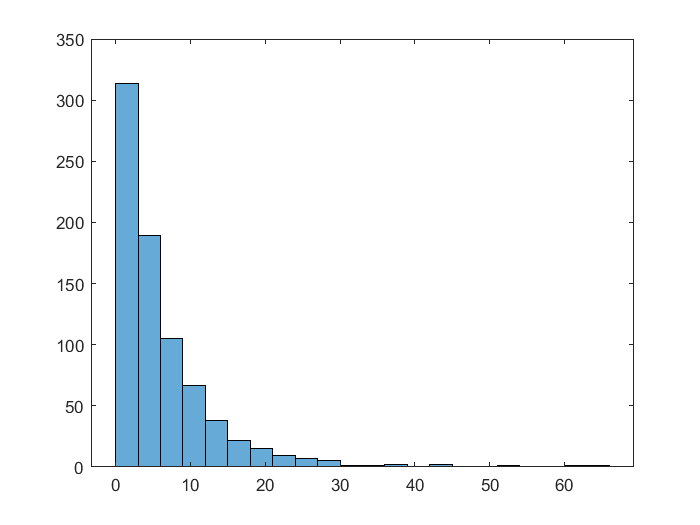

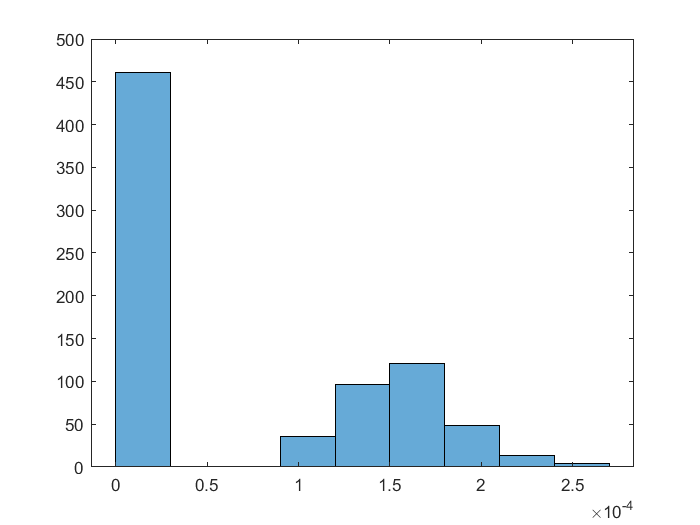

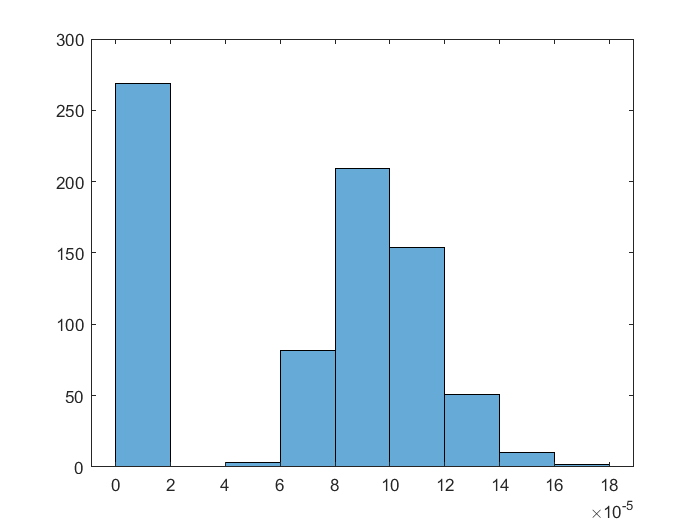

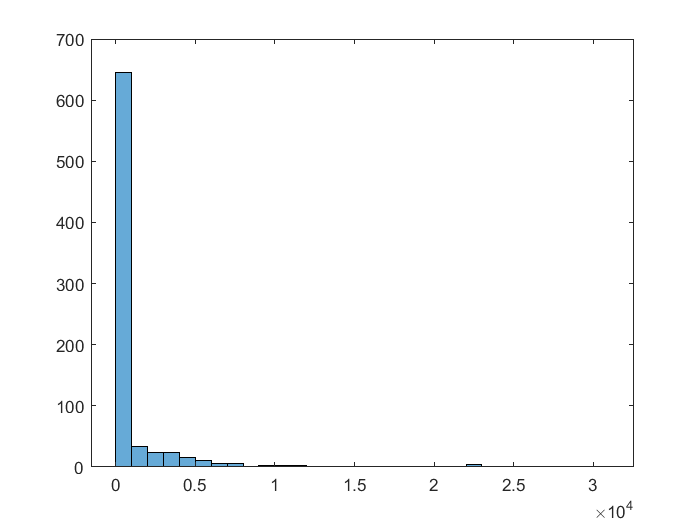

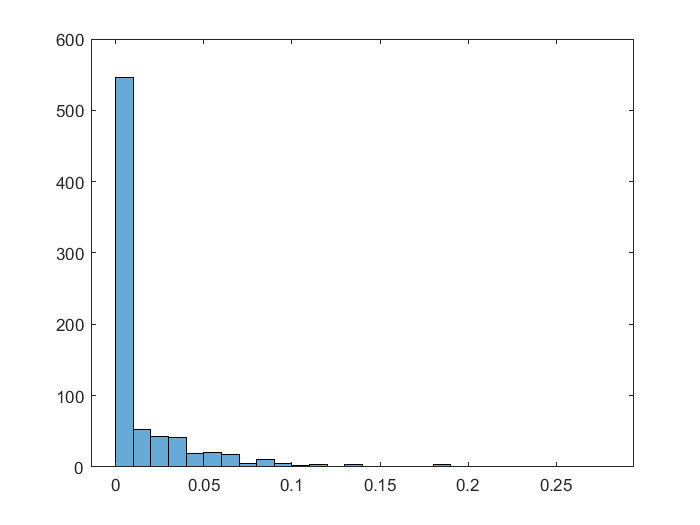

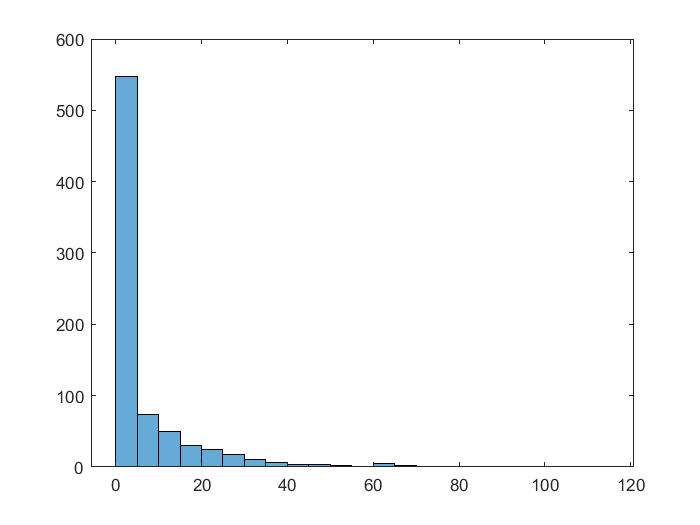

graph


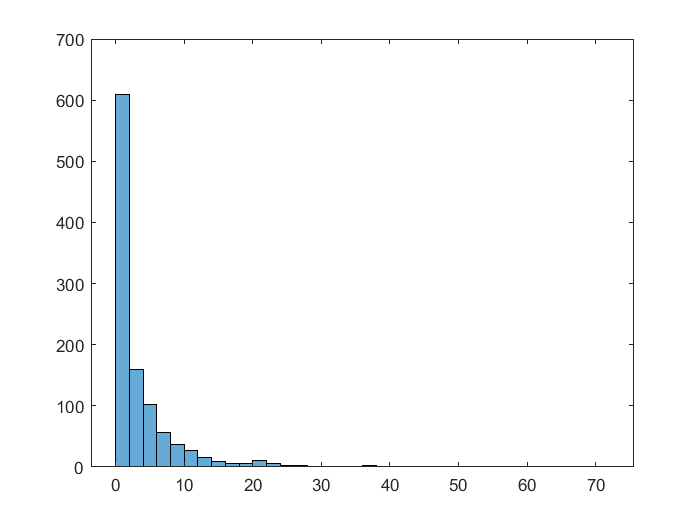

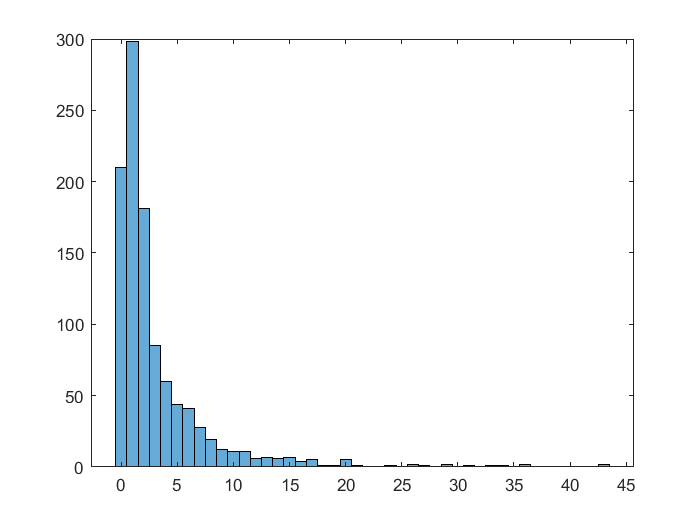

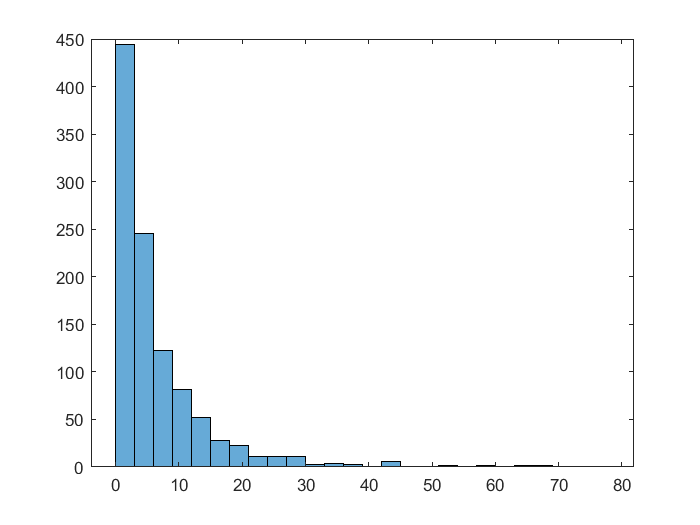

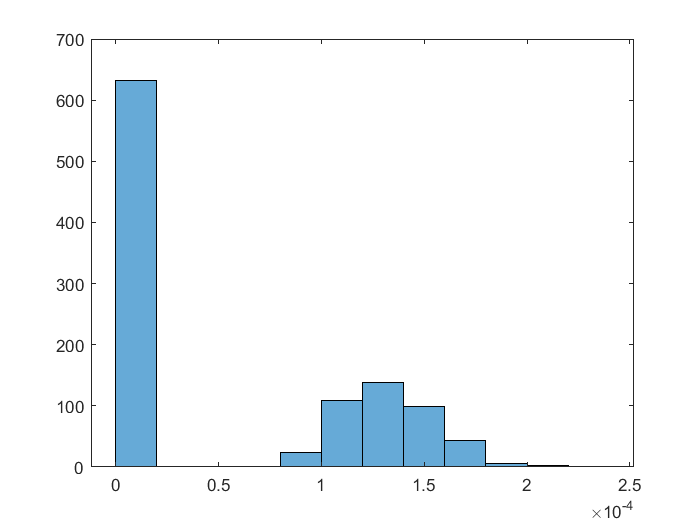

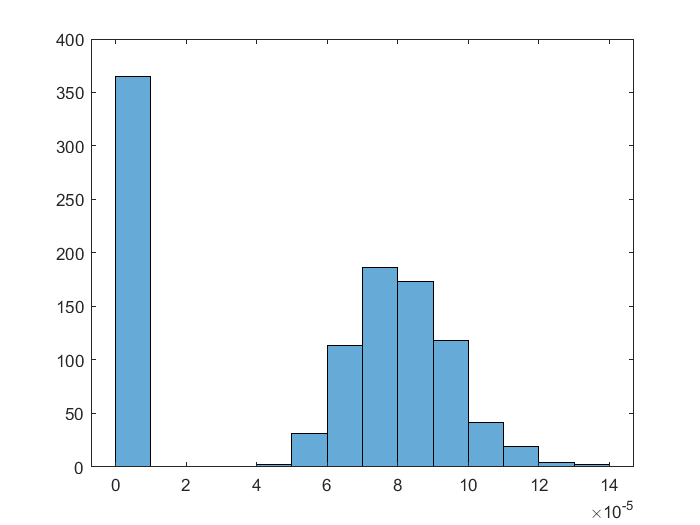

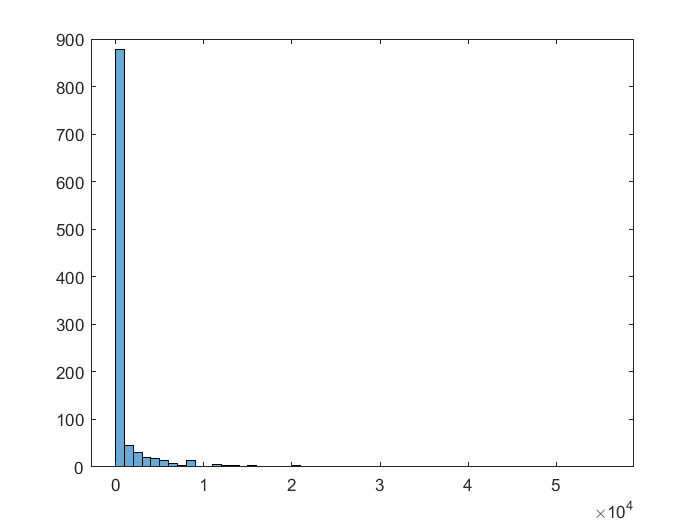

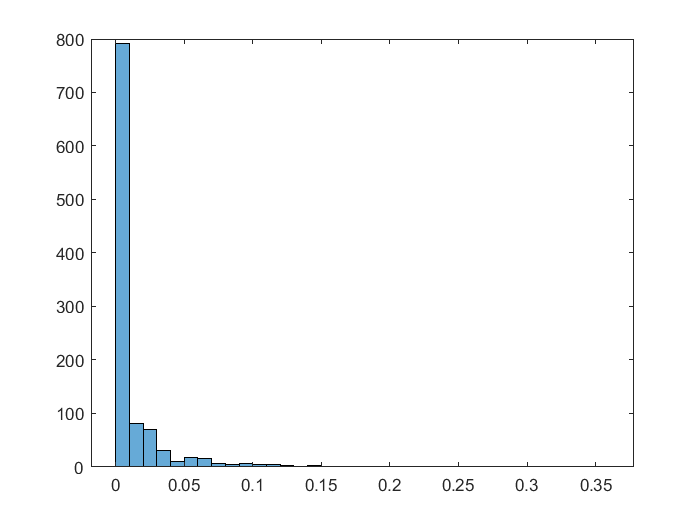

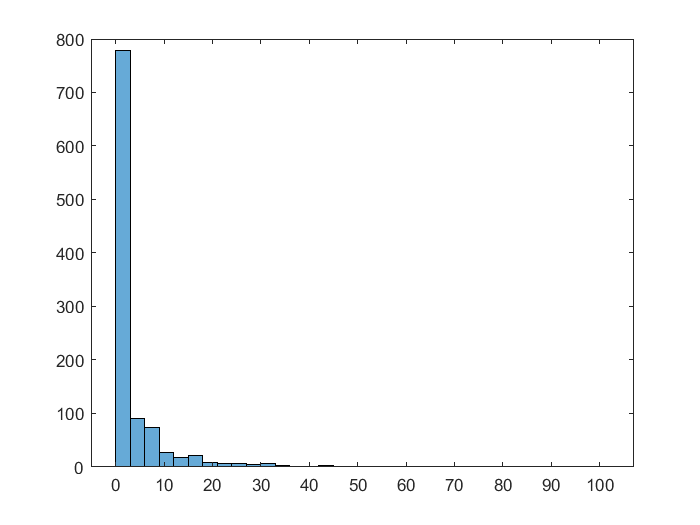

graph


for i = 1:1:N
    
    indegree_ranks = centrality(Graphs{i},'indegree');
    histogram(indegree_ranks)
    figure()
    
    outdegree_ranks = centrality(Graphs{i},'outdegree');
    histogram(outdegree_ranks)
    figure()
    
    degree_ranks = indegree_ranks+outdegree_ranks;
    histogram(degree_ranks)
    figure()
    
    incloseness_ranks = centrality(Graphs{i},'incloseness');
    histogram(incloseness_ranks)
    figure()
    
    outcloseness_ranks = centrality(Graphs{i},'outcloseness');
    histogram(outcloseness_ranks)
    figure()
    
    betweenness_ranks = centrality(Graphs{i},'betweenness');
    histogram(betweenness_ranks)
    figure()
    
    %eigenvector centrality
    A = full(adjacency(Graphs{i}));
    [V,D] = eig(A.');
    [~,idx] = max(diag(D));
    ec = abs(V(:,idx));
    eigenvector_ranks = reshape(ec, length(ec), 1);
    histogram(eigenvector_ranks)
    figure()

    
    %katz centrality
    [l1,idx] = max(diag(D));
    ec = abs(V(:,idx));
    a = 1/ceil(l1);
    I = eye(size(A.'));
    katz_ranks = (inv(I-a*A.')-I)*ones(size(A,1),1);
    histogram(katz_ranks(:,1))
    figure()

    
    disp('graph')
end

**5ο ερώτημα**


TimeGraphs = {digraph};
NewGraphs ={digraph};

for i = 2:1:N-1
    TimeGraphs{end+1} = digraph;
    NewGraphs{end+1} = digraph;
end

for i = 1:1:N-1
    
    nodes = intersect(Graphs{i}.Nodes,Graphs{i+1}.Nodes);
    TimeGraphs{i} = addnode(TimeGraphs{i}, nodes);
    
     tem = table2cell(Graphs{i}.Edges);
     
     for j = 1:1:size(tem,1)
         if findnode(TimeGraphs{i},char(tem{j}(1))) ~= 0 && findnode(TimeGraphs{i},char(tem{j}(2))) ~= 0 && ~strcmp(char(tem{j}(1)), char(tem{j}(2)))
             TimeGraphs{i} = addedge(TimeGraphs{i}, char(tem{j}(1)), char(tem{j}(2)));
         end
     end
     
     tem = table2cell(Graphs{i+1}.Edges);
     TempEdges = {};
     
     for j = 1:1:size(tem,1)
         if findnode(TimeGraphs{i},char(tem{j}(1))) ~= 0 && findnode(TimeGraphs{i},char(tem{j}(2))) ~= 0 && ~strcmp(char(tem{j}(1)), char(tem{j}(2)))
             NewGraphs{i} = addedge(NewGraphs{i}, char(tem{j}(1)), char(tem{j}(2)));
         end
     end
    
end


numnodes(TimeGraphs{1})

ans = 314

numnodes(NewGraphs{1})

ans = 264

numedges(TimeGraphs{1})

ans = 1473

numnodes(TimeGraphs{2})

ans = 381

numedges(TimeGraphs{2})

ans = 1216

numnodes(TimeGraphs{3})

ans = 566

numedges(TimeGraphs{3})

ans = 1524

**6ο ερώτημα**

Sgd={};
Scn={};
Sjc={};
Sa={};
Spa={};

for i = 1:1:N-1
    tempScn = zeros(numnodes(TimeGraphs{i}));
    tempSjc = tempScn;
    tempSa = tempScn;
    tempSpa = tempScn;
    
    Sgd{end+1} = distances(TimeGraphs{i});
    
    Sgd{end}(isinf(Sgd{end})|isnan(Sgd{end})) = 0;
    
    for j = 1:1:numnodes(TimeGraphs{i})
        
        neighbors1 = successors(TimeGraphs{i},char(TimeGraphs{i}.Nodes(j,1).(1)));
        
        for p = 1:1:numnodes(TimeGraphs{i})
            
            neighbors2 = successors(TimeGraphs{i},char(TimeGraphs{i}.Nodes(p,1).(1)));
            
            commonNeighbors = intersect(neighbors1,neighbors2);
            
            tempScn(j,p) = size(commonNeighbors,1);
            
            tempSjc(j,p) = size(commonNeighbors,1)/size(union(neighbors1,neighbors2),1);
            
            tempSpa(j,p) = size(neighbors1,1)*size(neighbors2,1);
            
            if size(commonNeighbors,1) > 0
                
                for rt = 1:1:size(commonNeighbors,2)
                    neighborDegree = size(successors(TimeGraphs{i},commonNeighbors{rt}),1);
                    tempSa = tempSa + (1/log(neighborDegree));
                end
            
            end
            
        end
        
    end
    
    Scn{end+1} = tempScn;
    
    Sjc{end+1} = tempSjc;
    
    Sa{end+1} = tempSa;
    
    Spa{end+1} = tempSpa;
    
end


**7ο ερώτημα**


for i = 1:1:N-1
    
    %Graph distance accuracy
    [~, sortIndex] = sort(Sgd{i}(:), 'descend');  
    maxIndex = sortIndex(1:(numel(Sgd{i})*Pgd/100));
    counter = 0;
    for j = 1:1:size(maxIndex,1)
        [row,col] = ind2sub(size(Sgd{i}),maxIndex(j));
        try
            if findedge(NewGraphs{i},char(TimeGraphs{i}.Nodes(row,1).(1)),char(TimeGraphs{i}.Nodes(col,1).(1))) ~= 0
            counter = counter + 1;
            end
        catch ME
            
        end
        
    end
    GraphDistanceAccuracy = counter/size(maxIndex,1)
    
    
    %Common neighbors accuracy
    [~, sortIndex] = sort(Scn{i}(:), 'descend');  
    maxIndex = sortIndex(1:(numel(Scn{i})*Pcn/100));
    counter = 0;
    for j = 1:1:size(maxIndex,1)
        [row,col] = ind2sub(size(Scn{i}),maxIndex(j));
        try
            if findedge(NewGraphs{i},char(TimeGraphs{i}.Nodes(row,1).(1)),char(TimeGraphs{i}.Nodes(col,1).(1))) ~= 0
            counter = counter + 1;
            end
        catch ME
            
        end
        
    end
    CommonNeighborsAccuracy = counter/size(maxIndex,1)
    
    
    %Jaccard’s Coefficient accuracy
    [~, sortIndex] = sort(Sjc{i}(:), 'descend');  
    maxIndex = sortIndex(1:(numel(Sjc{i})*Pjc/100));
    counter = 0;
    for j = 1:1:size(maxIndex,1)
        [row,col] = ind2sub(size(Sjc{i}),maxIndex(j));
        try
            if findedge(NewGraphs{i},char(TimeGraphs{i}.Nodes(row,1).(1)),char(TimeGraphs{i}.Nodes(col,1).(1))) ~= 0
            counter = counter + 1;
            end
        catch ME
            
        end
        
    end
    JaccardsCoefficientAccuracy = counter/size(maxIndex,1)
    
    
    
     %Adamic/adar accuracy
    [~, sortIndex] = sort(Sa{i}(:), 'descend');  
    maxIndex = sortIndex(1:(numel(Sa{i})*Pa/100));
    counter = 0;
    for j = 1:1:size(maxIndex,1)
        [row,col] = ind2sub(size(Sa{i}),maxIndex(j));
        try
            if findedge(NewGraphs{i},char(TimeGraphs{i}.Nodes(row,1).(1)),char(TimeGraphs{i}.Nodes(col,1).(1))) ~= 0
            counter = counter + 1;
            end
        catch ME
            
        end
        
    end
    AdamicAccuracy = counter/size(maxIndex,1)
    
    
    
    %Preferential Attachment accuracy
    [~, sortIndex] = sort(Spa{i}(:), 'descend');  
    maxIndex = sortIndex(1:(numel(Spa{i})*Ppa/100));
    counter = 0;
    for j = 1:1:size(maxIndex,1)
        [row,col] = ind2sub(size(Spa{i}),maxIndex(j));
        try
            if findedge(NewGraphs{i},char(TimeGraphs{i}.Nodes(row,1).(1)),char(TimeGraphs{i}.Nodes(col,1).(1))) ~= 0
            counter = counter + 1;
            end
        catch ME
            
        end
        
    end
    PreferentialAttachmentAccuracy = counter/size(maxIndex,1)
    
end